# KF tuning with fminsearch optimization

The search variables $x_1 ,x_2$ are the exponents of $q_i =e^{x_1 }$ and $q_F =e^{x_2 }$ to ensure positiveness

clc
clf
clear all
close all
rng(0)

## Load data

data = load('KF_TuningData.mat').out';

## Initialize

% qi_init = 1e-4;
% qF_init = 1e-4;
qi_init = 0.0057223677;
qF_init = 0.0008111308;
x_init = log([qi_init, qF_init]);

## Cost function wrapper

do_plot = false;
obj_fcn = @(u) KF_simulate(struct('qi', exp(u(1)), 'qF', exp(u(2))), data, do_plot);

## Optimize

options = optimset('Display', 'iter', ...
                   'TolFun', 1e-5, ...
                   'TolX', 1e-5, ...
                   'MaxIter', 50);

tic
[x_opt, cost_min] = fminsearch(obj_fcn, x_init, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1      0.000188611         
     1            3      0.000188611         initial simplex
     2            5      0.000188611         contract outside
     3            7      0.000188611         contract inside
     4            8      0.000188611         reflect
     5           10      0.000188611         contract inside
     6           12      0.000188611         contract inside
     7           14      0.000188611         contract inside
     8           16      0.000188611         contract inside
     9           18      0.000188611         contract outside
    10           20      0.000188611         contract inside
    11           21      0.000188611         reflect
    12           23      0.000188611         contract inside
    13           25      0.000188611         contract inside
    14           27      0.000188611         contract inside
    15           28      0.000188611         reflect
    

toc

Elapsed time is 10.146347 seconds.



qi_opt = exp(x_opt(1));
qF_opt = exp(x_opt(2));
fprintf('%.10f', qi_opt)

0.0056788544

fprintf('%.10f', qF_opt)

0.0008430168

## Plot resulting filtering

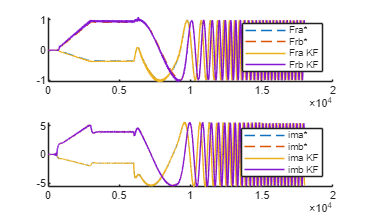

ans = 1.8861e-04

x = struct();
x.qi = qi_opt;
x.qF = qF_opt;
do_plot = true;
KF_simulate(x, data, do_plot)